## Quantitave Exercise

Pre-processing of the data

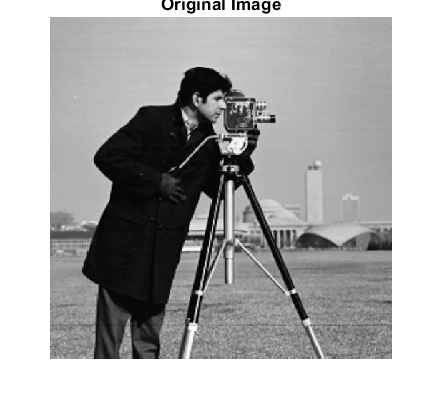

clear all; close all; format long;
preprocess_start = cputime;
I1 = imread('cameraman.jpg');
figure(1);
imshow(I1);
title('Original Image')

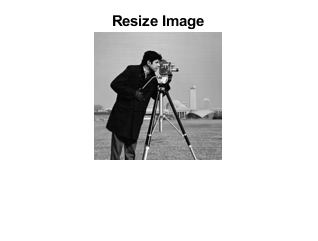

I2 = imresize(I1, [128, 128]);
figure(2);
imshow(I2);
title('Resize Image')

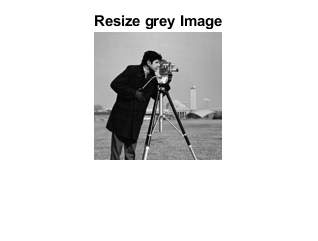

%To detect if the image needs resizing and grey filter
[rows columns numberOfColorBands] = size(I1);
if(numberOfColorBands == 3)
    pre_image = im2gray(I2);
    figure(3);
    imshow(pre_image);
    title('Resize grey Image')
else 
    pre_image = I2;
end


hex_pre_image = dec2hex(pre_image);
fid = fopen('ImageRawArrayHex.txt', 'w');

if fid == -1, error ('Cannot open file'); end
[rows columns numberOfColorBands] = size(I1);
%fprintf(fid, 'Size: %d\n', size(pre_image));
fprintf(fid, '%02X\n', pre_image);
fclose(fid);
preprocess_end = cputime - preprocess_start %in seconds

preprocess_end =    1.671875000000000


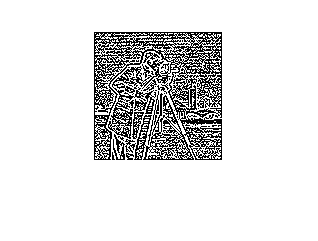




% MATLAB code for Edge detection using Laplacian Filter.
laplacian_start = cputime;
k1=double(pre_image);
% Define the Laplacian filter.
Laplacian=[0 1 0; 1 -4 1; 0 1 0];
% Convolve the image using Laplacian Filter
k2=conv2(k1, Laplacian, 'same');
% Display the image.
figure(4);
imshow(k2);

%title('Edge detection of Lena using Laplacian filter');
laplacian_end = cputime - laplacian_start % in seconds

laplacian_end =    0.265625000000000



%MATLAB code for Edge detection using Difference of Gaussian.
gaussian_start = cputime;
k3 = 10;
sigma1 =  0.5;
sigma2 = sigma1*k3;

hsize = 5;

gauss1 = fspecial('Gaussian', hsize, sigma1);
gauss1_mul = gauss1.*400;
gauss1_rond = round(gauss1_mul);
gauss1_hex = dec2hex(gauss1_rond);
gauss2 = fspecial('Gaussian', hsize, sigma2);

%gauss1 = imfilter(pre_image,h1,'replicate');
%gauss2 = imfilter(pre_image,h2,'replicate');

dogImg = gauss2 - gauss1;
dogFilterImage = conv2(pre_image, gauss1, 'same');
%hex_dogFilterImage = hex2dec(dogFilterImage);
fid = fopen('GoldenImageHexVec.txt', 'w');
if fid == -1, error ('Cannot open file'); end
fprintf(fid, '%08X ', dogFilterImage);
fclose(fid);

figure(5);
imshow(dogFilterImage)

%title('Edge detection of Lena using Differences of Gaussian');
gaussian_end = cputime - gaussian_start %in seconds

gaussian_end =    0.390625000000000


%putting the image back together

filename = 'outArrayHex.txt'; %output file I created
q = quantizer('fixed', 'nearest', 'saturate', [16 0]);% quantizer object for num2hex function  
FID = fopen(filename);
dataFromfile = textscan(FID, '%s');% %s for reading string values (hexadecimal numbers)
dataFromfile = dataFromfile{1};
decData = hex2num(q, dataFromfile);
decData = cell2mat(decData);
fclose(FID);

outImg = reshape(decData,[128 128]);

Error using reshape
Number of elements must not change. Use [] as one of the size inputs to automatically calculate the appropriate size for that dimension.


imshow(outImg);